# Algebra Lineal

# 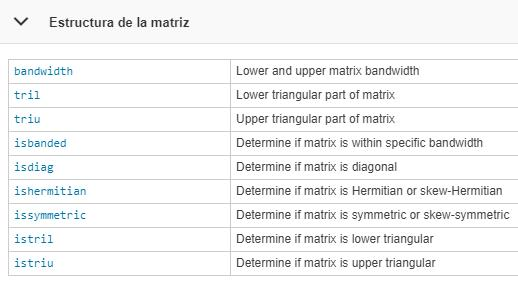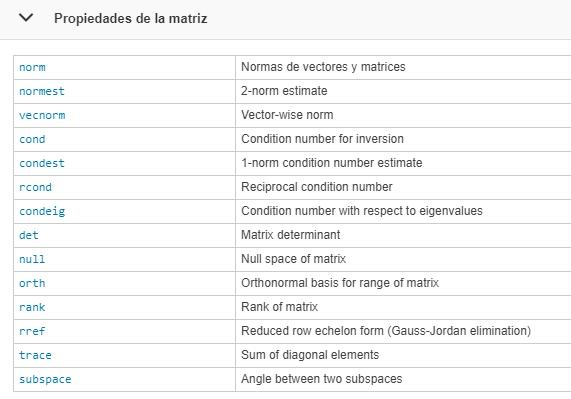

% manejo de matrices
% declaramos matrices m = [ 1 2 3 ; 4 5 6 ; 7 8 9 ];
% % matriz random en el rango de 1 a 10 A = randi(10,3,2);
% matriz de 0s B = ones(3,2); 
% %matriz de 1s C = ones(3,3); 
% % swap rows 
% %D=[1 3 4; 2 4 5]; 
% D =swapRow(A,1,2); 
% % multiply row 
% %D = multRow(A,2,2); 
% % add rows 
% %D =addRow(C,1,2,-1); 
% % add matrix 
% %C= A +B; 
% % transpose 
% %C=transpose(C);
 format rat
% format double
% whos A
% A=[1,2,3;7,8,9];
% B=[4,5,6;];
% C=dot(A(2,:),B)
% symbolic matrix
% a = sym('a',[1 4])
% a = sym('x_%d',[1 4])
% A = sym('a',[3 4])
% B = sym('x_%d_%d',4)
% A = sym('a',[2 2 2])
syms x y z
eqn1 = 2*x + y + z == 2;
eqn2 = -x + y - z == 3;
eqn3 = x + 2*y + 3*z == -10;
% [A,B] = equationsToMatrix([eqn1, eqn2, eqn3], [x, y, z])
%X = linsolve(A,B)
% sol = solve([eqn1, eqn2, eqn3], [x, y, z]);
% xSol = sol.x
% ySol = sol.y
% zSol = sol.z
% inversas
% inv(A)

% entendiendo la multiplicacion
A=sym('a',3);
B=sym('b',3);
C=A*B;
C11=dot(A(1,:),B(:,1));
C12=dot(A(1,:),B(:,2));
C13=dot(A(1,:),B(:,3));
C21=dot(A(2,:),B(:,1));
C22=dot(A(2,:),B(:,2));
C23=dot(A(2,:),B(:,3));
C31=dot(A(3,:),B(:,1));
C32=dot(A(3,:),B(:,2));
C33=dot(A(3,:),B(:,3));
C2=[C11 C12 C13 ; C21 C22 C23 ; C31 C32 C33];

calcular la inversa de una matriz

B=sym([2 3 ; 5 1])

$$B = \left(\begin{array}{cc} 2 & 3\\ 5 & 1 \end{array}\right)$$

A=sym(eye(2))

$$A = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

A1=multr(A,1,1/2)

$$A1 = \left(\begin{array}{cc} \frac{1}{2} & 0\\ 0 & 1 \end{array}\right)$$

A2=addr(A1,2,1,-5)

$$A2 = \left(\begin{array}{cc} \frac{1}{2} & 0\\ -\frac{5}{2} & 1 \end{array}\right)$$

A3=multr(A2,2,-2/13)

$$A3 = \left(\begin{array}{cc} \frac{1}{2} & 0\\ \frac{5}{13} & -\frac{2}{13} \end{array}\right)$$

A4=addr(A3,1,2,-3/2)

$$A4 = \left(\begin{array}{cc} -\frac{1}{13} & \frac{3}{13}\\ \frac{5}{13} & -\frac{2}{13} \end{array}\right)$$

A4*B

$$ans = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

## Tarea 1

#### Ej. 1

a)  

A=sym([2 -4 12 -10 58; -1 2 -3 2 -14;2 -4 9 -6 44])
A1=swapr(A,1,2)
A2=multr(A1,1,-1)
A3=addr(A2,2,1,-2)
A4=addr(A3,3,1,-2)
A5=addr(A4,2,3,-2)
A6=swapr(A5,2,3)
A7=addr(A6,2,3,-1)
A8=addr(A7,1,3,-1)
A9=addr(A8,1,2,-1)
A10=multr(A9,2,1/3)
A11=multr(A10,3,-1/2)
rref(A);

queda una ecuacion con 2 incognitas (not sure que pedo) 

comprobe qeu estuviera bien con rref

b)

A=sym([3 -3 3 9;2 -1 4 7; 3 -5 -1 7])
A1=multr(A,1,1/3)
A2=addr(A1,2,1,-2)
A3=addr(A2,3,1,-3)
A4=addr(A3,1,2,1)
A5=addr(A4,3,2,2)
% A6=addRow(A5,1,2,-3/2) ??? mejor fracciones no? nah
rref(A);

mismo caso que el a)

c)

A=sym([3 -3 3 9; 2 -1 4 7 ; 3 -5 -1 6])
A1=multr(A,1,1/3)
A2=addr(A1,2,1,-2)
A3=addr(A2,3,1,-3)
A4=addr(A3,1,2,1)
A5=addr(A4,3,2,2)
A6=multr(A5,3,-1)
rref(A);

Contradiccion en el ultimo row por tanto no es consistente

#### Ej 2

a)

syms t
A=sym([2 3 1 0 5;5 7 -4 0 0;1 0 0 -19 -35;0 1 0 13 25 ; 0 0 1 -1 0])
A1=addr(A,1,3,-2)
A2=swapr(A1,3,1)
A3=addr(A2,2,1,-5)
A4=swapr(A3,4,2)
A5=swapr(A4,3,5)
A6=addr(A5,4,2,-7)
A7=addr(A6,5,2,-3)
A8=addr(A7,4,3,4)
A9=addr(A8,5,3,-1)
rref(A);

ya no se que mas **aqui hay algo qeu teines que corregir lo antes posible**

respuesta alternativa

syms t x y z 
q1= x==19*t
q2= y==25-14*t
q3= z==t
q4= 2*x +3*y + z ==5
q5= 5*x + 7*y-4*z ==0
s=solve(q1,q2,q3,q4,q5);
s.t
s.x
s.y
s.z

b)

A=sym([2 5 9 3 0 0 -1 ; 1 2 4 0 0 0 1; 1 0 0 0 0 -19 -35; 0 1 0 0 1 0 0 ; 0 0 0 1 0 1 0; 0 0 -1 0 -1 -3 3 ])
A1=swapr(A,3,1)
A2=addr(A1,2,1,-1)
A3=addr(A2,3,1,-2)
A4=swapr(A3,4,2)
A5=addr(A4,3,2,-5)
A6=addr(A5,4,2,-2)
A7=multr(A6,6,-1)
A8=swapr(A7,6,3)
A9=addr(A8,4,3,-4)
A10=addr(A9,6,3,-9)
A11=swapr(A10,5,4)
A12=addr(A11,6,4,-3)
A13=multr(A12,5,-1/6)
A14=addr(A13,6,5,14)
A15=addr(A14,2,5,-1)
A16=addr(A15,3,5,-1)
rref(A);

#### Ej 3

A=sym([1 -2 4 12; 2 -1 5 18 ; -1 3 -3 -8])
A1=addr(A,2,1,-2)
A2=addr(A1,3,1,1)
A3=multr(A2,2,1/3)
A4=addr(A3,3,2,-1)
A5=addr(A4,1,2,2)
A6=addr(A5,1,3,-1)
A7=addr(A6,2,3,1/2)
A8=multr(A7,3,1/2)
rref(A);

#### Ej 4     PROBABLEMENTE SALGA EN EL EXAMEN

syms a
syms b
syms c
A=sym([1 2 -1 a; 2 1 3 b; 1 -4 9 c])

$$A = \left(\begin{array}{cccc} 1 & 2 & -1 & a\\ 2 & 1 & 3 & b\\ 1 & -4 & 9 & c \end{array}\right)$$

A1=addr(A,2,1,-2)

$$A1 = \left(\begin{array}{cccc} 1 & 2 & -1 & a\\ 0 & -3 & 5 & b-2\,a\\ 1 & -4 & 9 & c \end{array}\right)$$

A2=addr(A1,3,1,-1)

$$A2 = \left(\begin{array}{cccc} 1 & 2 & -1 & a\\ 0 & -3 & 5 & b-2\,a\\ 0 & -6 & 10 & c-a \end{array}\right)$$

A3=addr(A2,3,2,-2) %matriz escalonada

$$A3 = \left(\begin{array}{cccc} 1 & 2 & -1 & a\\ 0 & -3 & 5 & b-2\,a\\ 0 & 0 & 0 & 3\,a-2\,b+c \end{array}\right)$$

A4=multr(A3,2,-1/3)

$$A4 = \left(\begin{array}{cccc} 1 & 2 & -1 & a\\ 0 & 1 & -\frac{5}{3} & \frac{2\,a}{3}-\frac{b}{3}\\ 0 & 0 & 0 & 3\,a-2\,b+c \end{array}\right)$$

A5=addr(A4,1,2,-2)

$$A5 = \left(\begin{array}{cccc} 1 & 0 & \frac{7}{3} & \frac{2\,b}{3}-\frac{a}{3}\\ 0 & 1 & -\frac{5}{3} & \frac{2\,a}{3}-\frac{b}{3}\\ 0 & 0 & 0 & 3\,a-2\,b+c \end{array}\right)$$

rref(A);

jalaba desde la matriz escalonada

#### Ej 5

A= sym([1 -1 2 3;2 -2 5 4;1 2 -1 -3; 0 2 2 1])
A1=addr(A,2,1,-2)
A2=addr(A1,3,1,-1)
A3=swapr(A2,2,3)
A4=multr(A3,2,1/3)
A5=addr(A4,4,2,-2)
A6=addr(A5,4,3,-4) %escalonada
A7=addr(A6,1,2,1)
A8=addr(A7,2,1,1)
A9=addr(A8,1,3,-1)
rref(A);

inconsistente

#### Ej 6

a) falso -> tendria m renglones

b) falso -> uno inconsistente deberia tener una infinidad de soluciones

c) verdadero

d) verdadero

e) verdadero por transividad

#### Ej 7

syms a 
syms b
syms c
A= sym([a b*(-1) c*(-1)^2 6;
    a b*(2) c*(2)^2 0;
    a b*(3) c*(3)^2 2])
A1=addr(A,2,1,-1)
A2=addr(A1,3,1,-1)
A3=multr(A2,2,1/3)
A4=addr(A3,3,2,-4)
A5=multr(A4,3,1/4)
A6=addr(A5,1,3,-1)
A7=addr(A6,2,3,-1)
A8=addr(A7,1,2,1)

la cuadratica seria $2-3x+x^{2}$

#### Ej 8

syms a 
syms b
syms c
%???

**sin resolver**

#### Ej 9

syms t
A=[2 1 5;4 -2 t]

a)

A1=addr(A,2,1,-2)
A2=addr(A1,1,2,1/4)
A3=multr(A2,1,1/2)
A4=multr(A3,2,-1/4)

**definitivamente no se que pedo**

b) tampoco en esta

#### Ej 10

syms a b c d
A=[1 3,1, a;-1 -2 1 b;3 7 -1 c]
A1=addr(A,2,1,1)
A2=addr(A1,3,1,-3)
A3=addr(A2,1,2,-3)
A4=addr(A3,3,2,2)

tiene que ser $2b-a+c=0
$ para que sea consistente

#### Ej 11

a) 

 3 variables y solo 2 ecuaciones sin solucion

A= sym([1 1 1 1;
    0 0 0 1])

b)    

2 variables 3 ecuaciones **(no se si tiene solucion unica)**

A=sym([1 1 1;
    1 1 1;
    1 1 1])

#### Ej 12

(3,4,-2) (como se si es la unica)

A=sym([5 -1 2 7;-2 6 9 0; -7 5 -3 -7])
A1=multr(A,1,1/5)
A2=addr(A1,2,1,2)
A3=addr(A2,3,1,7)
A4=multr(A3,2,5/28)
A5=addr(A4,1,2,1/5)
A6=addr(A5,3,2,-18/5)
A7=multr(A6,3,-2/13)
A8=addr(A7,2,3,-7/4)
A9=addr(A8,1,3,-3/4)

**no se como definir cuales otras respuestas existen**

#### Ej 13

syms h k
A=[2 -1 h; -6 -3 k]
A1=addr(A,2,1,3)
A2=multr(A1,1,1/2)
A3=multr(A2,2,-1/6)
A4=addr(A3,1,2,1/2)

**para todos, no?**

#### Ej 14

a)

A=sym([0 1 4 -5;1 3 5 -2 ; 3 7 7 6])
A1=swapr(A,1,2)
A2=addr(A1,3,1,-3)
A3=addr(A2,3,2,2)
A4=addr(A3,1,2,-3)
rref(A);

no tiene solucion

b)

A=sym([1 -3 4 -4 ; 3 -7 7 -8 ; -4 6 -1 7])
A1=addr(A,2,1,-3)
A2=addr(A1,3,1,4)
A3=multr(A2,2,1/2)
A4=addr(A3,1,2,3)
A5=addr(A4,3,2,6)
rref(A);

no tiene solucion

c)

A=sym([1 0 -3 8 ; 2 2 9 7; 0 1 5 -2])
A1=swapr(A,2,3)
A2=addr(A1,3,1,-2)
A3=addr(A2,3,2,-2)
A4=multr(A3,3,1/5)
A5=addr(A4,2,3,-5)
A6=addr(A5,1,3,3)
rref(A);

si habemus respuesta

#### Ej 15

A=sym([1 -4 1;2 -1 -3; -1 -3 4])
A1=addr(A,3,1,1)
A2=addr(A1,2,1,-2)
A3=addr(A2,3,2,1)
A4=multr(A3,2,1/7)
A5=addr(A4,1,2,4)

**creo que si?? pero cual es el punto en x_3**

#### Ej 16

A=sym([ 1 2 1 4;0 1 -1 1;1 3 0 0])
A1=addr(A,3,1,-1)
A2=addr(A1,1,2,-2)
A3=addr(A2,3,2,-1)

el sistema es inconsistente entonces supongo que no?

#### Ej 17

syms h

a)

A=[1 h -3; -2 4 6]
A1=multr(A,2,-1/2)
A2=addr(A1,2,1,-1)

ni siquiera puede inconsistentar el sistema 

b)

mismo que a)

c)

mismo que a)

d)

mismo que a)

**seguro I am missing something que si pueda inconsistentar el sistema**

#### Ej 18

ni hay sistema presentado a continuacion

#### Ej 19

tampoco hay sistema de ecuaciones a continuacion

#### Ej 20

syms a b c d
A=[a b 0; c d 0]

**not a clue**

#### Ej 21

syms a b c
A=[a*1^2 b*1 c -5;
   a*(-1)^2 b*-1 c 1;
   a*2^2 b*2 c 7;]
A1=addr(A,2,1,-1)
A2=addr(A1,3,1,-4)
A3=multr(A2,2,-1/2)
A4=addr(A3,1,2,-1)
A5=addr(A4,3,2,2)
A6=multr(A5,3,-1/3)
A7=addr(A6,1,3,-1)

la parabola seria 

 
$$p\left(x\right)=5x^2 -3x-7$$


#### Ej 22

sin azufre:     1 ton = 5 m + 4 r

con azufre:    1 ton = 4 m + 2 r

planta M = 3 horas

planta R = 2 horas

**la neta no se como taclear este problema**

## Tarea 2

#### Ej 1

A=[5 4;-1 7;9 -3];
sym(A)
B=[-3 0;4 2;5 -7];
sym(B)

a) 

sym(A+B)

b)

sym(2*A+B)

c) 

sym(transpose(A))

#### Ej 2

A=[9;2;-1];
B=[0 -1 4;6 -8 2;-4 5 9];
D=[-3; 0;2];
sym(A);
sym(B);
sym(D);

a)    

sym(A+B)

b)

sym(3*A+2*D)

c)

sym(-A)

d)

sym(transpose(B))

#### Ej 3

A=[1 0 ;0 1]; 
B=[0 1;-2 5];
C=[-1 0 3;5 7 2];

a)

A*B

b)

A*C

c)

A^2

d)

B*C

e)

transpose(A*B)

#### Ej 4

A=sym([0 1; 0 3; 5 6]);
B=sym([-1 0;3 5;2 6]);
C=sym([-4 0;3 2]);
d=sym([5 0 ; -2 1]);

a)

2*A-3*(B*C)

b) checa este pedo as well

% A*C-B*D algun pedo con la cantidad de row y columans

c) checa este pedo

% C^3-2*(D^2) algun pedo con el power 

d)

transpose(2*A-3*(B*C))

#### Ej 5

A=[0 3 -5; 2 6 3 ; 1 0 -2];
B=[-1 2 -3 ; 5 7 2 ; 0 1 6];
C=sym(A*B)
D=sym(B*A)

a)

C(3,1)
dot(A(3,:),B(:,1))

b)

D(1,2)

#### Ej 6

A=sym('a',[3 3]);
A(3,:)=zeros
B=sym('b',3)
C=A*B    %si sale el ultimo renglon con 0s
C_31=dot(A(3,:),B(:,1))
C_32=dot(A(3,:),B(:,2))
C_33=dot(A(3,:),B(:,3))

#### Ej 7

Sea A una matriz de mxn tal que A = -A: Prueba que A = 0

A=sym('a',3)
-A

Sabemos que A=-A si son iguales termino a termino, esto quiere decir que 

a11=-a11 ... a33=-a33

esto solo se puede dar si todos los valores de A son iguales a 0

la matriz que tiene todas sus elementos iguales a 0 a es la matriz 0

entonces A = 0

#### Ej 8

syms a b c d

a) 

A=[a b ; c d]
B=[c-3*d -d ; 2*a+d a+b]
C=[A(1,1) B(1,1);A(1,2) B(1,2);A(2,1) B(2,1);A(2,2) B(2,2)]
C=sym([1 0 -1 3 0; 0 1 0 1 0; -2 0 1 -1 0; -1 -1 0 1 0])
C1=addr(C,3,1,2)
C2=addr(C1,4,1,1)
C3=addr(C2,4,2,1)
C4=multr(C3,3,-1)
C5=addr(C4,4,3,1)
C6=addr(C5,1,3,1)

no se que pedo

b)

sym(2*[1 1 ; -3 1])
A=sym([1 -1 0 0 2 0; 0 1 -1 0 2 0; 0 0 1 -1 -6 0; -1 0 0 1 2 0])
A1=addr(A,4,1,1)
A2=addr(A1,1,2,1)
A3=addr(A2,4,2,1)
A4=addr(A3,4,3,1)
A5=addr(A4,2,3,1)
A6=addr(A5,1,3,1)

solucion alternativa

eq1=a-b==2
eq2=b-c==2
eq3=c-d==-6
eq4=d-a==2
S=solve(eq1,eq2,eq3,eq4);
a=S.a
b=S.b
c=S.c
d=S.d

todo correcto

#### Ej 9

a)

A=sym([3 2 1 ; 5 1 0]); 
B=sym([3 0 -2 ; 1 -1 2]);
5*B
C=sym(A-5*B)

b)

A=sym([1 -5 4 0; 2 1 0 6]);
A=transpose(A)

#### Ej 10

a)

B=sym([1 -1 0; 1 2 4]);
C=sym([2 1; 0 5 ; 3 8 ]);
transpose(C)
%transpose(A+3*B)=C despejamos A manualmente
%A+3*B=transpose(C) 
A=transpose(C)-3*B

b)

B=sym([1 0 ; 0 2]);
C=sym([8 0 ; 3 1]);
% (3*A' + 2*B)'=C
% 3*A' + 2*B = C'
% 3*A' = C' - 2*B
% A' = ( C' - 2*B )/3
A = (( C' - 2*B )*(1/3))'

ps se armo

#### Ej 11

demo que no se hacer porque no se como son las matrices simetricas

#### Ej 12

11 pero de diagonales

#### Ej 13

11

#### Ej 14

A=sym('a',3)

para que sean iguales tienen que ser iguales todos sus terminos

un ejemplo de sus terminos es aij=k*aji

**??**

#### Ej 15

11

a)

b)

#### Ej 16

a)

sym([1 3 ; 0 -2]*[2 -1 ; 0 1])

b)

sym([1 -1 2 ; 2 0 4]*[2 3 1 ;1 9 7 ;-1 0 2])

c) **interesante**

syms a b c
A=[2 3 1 ; 5 7 4];
B=[a 0 0;0 b 0;0 0 c];
C=sym(A*B)
c11=dot(A(1,:),B(:,1))
c12=dot(A(1,:),B(:,2))
c13=dot(A(1,:),B(:,3))
c21=dot(A(2,:),B(:,1))
c22=dot(A(2,:),B(:,2))
c23=dot(A(2,:),B(:,3))
C23=dot(A(2,:),B(:,3))

#### Ej 17 

despejamos la matriz que queremos el pedo radica en qeu se multiplican y no se como **dividir matrices**

syms a a1 b b1
A=[a b ; a1 b1];

a)

B= [3 -5 ; -1 2 ];
C=[1 -1 ; 2 0];
%A*B=C
A=C/B

b)

B=[2 1 ; -1 2 ];
C=[7 2 ; -1 4];
A=C/B

#### Ej 18

#### Ej 19

#### Ej 20

#### Ej 21

#### Ej 22

#### Ej 23

#### Ej 24

#### Ej 25

#### Ej 26

#### Ej 27

#### Ej 28

#### Ej 29

#### Ej 30

#### Ej 31

#### Ej 32

A=

#### Ej 33

#### Ej 34

## Ejercicios de Kolman-Hill

#### 1.1

1-14 son sistemas lineales por metodo de eliminacion gaussiana, no los hare

15 - 

16 - 

17 -

18 - entonces porque metodo?

19 - solo expandes mas la matriz 

20 - igual que la 19

21 - no hay figura 1.2

22 - a) 0 b) ? c) ? 

23 - mismo que el ultimo de la tarea 2

24 - 26 son del tipo del 23

27 - ya lo resolvi en la tarea 1

28 - 23

#### Ejericios teoricos

T.1 - Demuestra que el sistema lineal que se obtiene al intercambiar dos ecuaciones en A tiene las mismas soluciones que A

T.2 - Demuestre que el sistema lineal obtenido al remplazar una ecuacion en A por un multiplo constante de la ecuacion diferente de cero, tiene exactamente las mismas soluciones que A

T.3 - Demuestre que el sistema lineal que se obtiene al remplazar una ecuacion en A por ella misma mas un multiplo de otra ecuacion en A tiene exactamente las mismas soluciones que A

T.4 - mismo que en tarea 1

#### 1.2

1- determinar valores especificos sin hacer toda la matriz

2 - sistema de ecuaciones sencillo presentado de forma medio rara

3 - 2

4 - 7 son operaciones de matrices sencillas

8 - combinacion lineal **?**

9 - 8 

10 - multiplicar una constante por una matriz de forma que te de otra, mas o menos se como hacerla pero vale la pena hacerla ** !!**

11 - 4-7

12 - 11

13 - Obtener una matriz a partir de una suma de matrices !!!

14-15 son 13 pero con vectores

#### Ej teoricos

T.1 - Demuestra que la suma y la diferencia de dos matrices diagonales es una matriz diagonal

T.2 - Demuestre que la suma y la diferencia de dos matrices escalares es una matriz escalar

T.3 - 4-7 pero simbolico

T.4 - sea 0 la matriz de n x n tal que todas sus entradas son cero. Demuestre que si k es un numero real y a es una matriz de n x n tal qeu kA=0 entonces k=0 o A=0

T.5 -

a) demuestre que la suma y la diferencia de dos matrices triangulares superiores es una matriz triangular superior

b) demuestre lo que a) pero con inferiores

c) demo que si una matriz es inferior y superior al mismo tiempo entonces es diagnoal

T.6 - 

a) demo que si A es superior A^t es inferior

b) viceversa de a)

T.7 - cuales son las entradas de la diagonal principal de A-A^t si A es matriz cuadrada

T.8 - si x es un n vector demuestre que x+0=x

T.9 - haga una lista de todos los posibles 2 vectores binarios ¿cuantos hay?

T.10 - T.9 pero con 3 vector

T.11 - T.9 pero con 4 vector

#### 1.3

#### Ej teoricos

T.1 - sea x un n vector 

a) es posible que x punto x sea negativo?

b) si x punto x = 0, cual es el valor de x?

T.2 - 

a) demuestre que a punto b = b punto a

b) demuestre que (a + b) punto c = a punto c + b punto c

c) demuestre que (ka) punto b = a punto (kb) = k(a punto b)

T.3 - 

a) demuestre uqe si A tiene una dila de ceros, AB tiene una fila de ceros

b) demuestre que si B tienen una columna de ceros, AB tiene una columna de ceros

T.4 - 

Demuestre que el producto de dos matrices diagonales es una matriz diagnoal

T.5 - 

demuestre que el producto de dos matrices escalares es una matriz escalar

T.6 -

a) demuester que el producto de dos matrices superiores es una matriz superior

ya existe en algun otro lado

b) demuestre que el prducto de dos matrices inferiores es una matriz inferior

T.7 - sean A y B matrices diagonales de nxn ¿es cierto que AB = BA?

T.8 - 

a) sea a una matriz de 1xn y B una matriz de nxp demuestre que el producto de matrices aB puede escribirse como una combinacion lineal de las filas de B en los qeu los coeficientes cson las entradas de a

b) sean

a=[1 -2 3];
B=[2 1 -4 ; -3 -2 3; 4 5 -2];
sym(a)
sym(B)

escriba aB como una combinacion lineal de las filas de B

T.9 - 

a) demuester que al jesima columna del producto de matrices AB es igual al producto de matrices A col_j(B)

b) demuestre que el iesima fila del producto de matrices AB es igual al producto de matrices fil_i(A)B

T.10 - sea A una matriz de mxn cuyas entradas son numeros reales, demuestre que si AA^t= 0 entonces A=0

T.11 - T.13 son de notacion sigma que ni al caso

T.14 - 

a) si u y v se consideran matrices de nx1 demuestre que u punto v = u^tv

b) lo mismo que a) pero u punto v = uv^t

c) si u se considerara una matriz de 1xn y v una matriz de nx1 demuestre que u punto v= uv

## Funciones

function A= swapr(A, row1, row2)
    A([row2, row1], :) = A([row1, row2], :);
end

function B = multr(B, row, factor)
    B(row,:) = B(row,:)*factor;
end

function C = addr(C, row1, row2, factor)
    C(row1,:) = C(row1,:)+C(row2,:)*factor;  
end